# **Modellazione e controllo in cascata della velocità di un servomotore DC a magneti permanenti mediante convertitore H bridge con modulazione PWM **

L'obiettivo di questo lavoro è la progettazione e la simulazione di un sistema di controllo in cascata costituito da due anelli chiusi (uno interno di corrente e uno esterno di velocità per la regolazione della velocità di un servomotore DC a magneti permanenti  [Maxon Motor RE 35 modello : 323890(Versione 24V, 90W)](https://www.maxongroup.com/en/drives-and-systems/brushed-dc-motors).

Il sistema utilizza un convertitore DC-DC a ponte H come stadio di potenza, il quale permette di variare la tensione applicata al motore in modo efficiente attraverso la tecnica della modulazione a larghezza d'impulso (PWM). Il progetto si articolerà nelle seguenti fasi:

- **Modellazione Dinamica**: Definizione delle funzioni di trasferimento del modulatore PWM, del filtro del convertitore, del modello elettromeccanico del motore e del sensore di velocità.

- **Analisi del Sistema**: Studio della risposta in frequenza e dei limiti di stabilità del sistema ad anello aperto.

- **Progettazione del sistema di  controllo**: Sviluppo e taratura di un sistema di controllo in cascata, finalizzato a garantire un’adeguata reiezione ai disturbi e un corretto inseguimento dei riferimenti, mantenendo al contempo buone prestazioni dinamiche del sistema, quali basso overshoot, ridotto tempo di salita ed errore a regime nullo

- **Simulazione**: Verifica del comportamento del sistema a fronte di variazioni di carico o di riferimento e in presenza di saturazioni di corrente e duty cycle.

## **Parametri caratteristici del sistema **

#### Convertitore H bridge  STMicroelectronics VNH7070AS :

- $V_{\textrm{in}} =24\;V$                                              *Tensione di alimentazione*

- $f_{\textrm{PWM}} =20\;\textrm{KHz}$                                      *Frequenza di commutazione del convertitore *

- $I_{\textrm{out}} =15\;A$                                              *Corrente nominale di uscita*

#### Motore DC  Maxon Motor RE 35 (Versione 24V, 90W) :

- $V_n =24\;V$                                               *Tensione nominale*

- $R_a =0,658\;\Omega \;\;$                                        *Resistenza di armatura*

- $L_a =0,191\;mH$                                       *Induttanza di armatura*

- $K_t =0,0292\;N\cdot m/A$                             *Costante di coppia*

- $K_e =0,0291\;N\cdot m/A$                             *Costante di forza contro-elettromotrice*

- $J=8,12\cdot {10}^{-6} \;\textrm{kg}\cdot m^2$                          *Costante di inerzia del rotore*

- $b=4,61\cdot {10}^{-6} \;N\cdot m\cdot s\;/\textrm{rad}$                 *Costante d'attrito viscoso*

- $n=6980\;\textrm{rpm}$                                         *Velocità nominale rotore*

- $I_s =42,2\;A$                                             *Corrente di spunto*

- $I_n =3,81\;A$                                             Corrente nominale

- $\tau_{\textrm{th}} =36,1\;s$                                             *Costante di tempo termica avvolgimento*

- $R_{\textrm{th}} =10,1\;K/W$                                      *Resistenza termica del motore*

%% Parametri del Convertitore H bridge  STMicroelectronics VNH7070AS
Vin = 24;          % Tensione di alimentazione [V]
fpwm = 20;         % Frequenza di commutazione del converitore PWM [KHz]
Iout = 15;         % Corrente nominale in uscita [A]

%% Parametri del Motore DC  Maxon Motor RE 35 (Versione 24V, 90W).
Vn = 24;           % Tensione nominale [V]
Ra = 0.568;        % Resistenza di armatura [Ohm]
La = 1.91e-4;      % Induttanza di armatura [H]
Kt = 0.0292;       % Costante di coppia [Nm/A]
Ke = 0.0291;       % Costante forza contro-elettromotrice [V/(rad/s)]
J = 8.12e-6;       % Costante d'inerzia del rotore [kg*m^2]
b = 4.61e-6;       % Costante d'attrito viscoso [Nm*s/rad]
n = 6980;          % Velocità nominale [rpm]
Is = 42.2;         %Corrente di stallo/spunto [A]
In = 3.81;         %Corrente nominale [A]
tau_term = 36.1;   %Costante di tempo termica avvolgimento [s]
Rth = 10.1;        %Resistenza termica motore [K/W]

### **Modellazione Dinamica**

Dopo aver definito i parametri costanti dell'intero sistema, si procede con la modellazione dello stesso. Partendo dalle equazioni caratteristiche nel dominio del tempo si passa alle funzioni di trasferimento nel dominio della frequenza s tramite trasformata di Laplace per ciascun componente del sistema. Nello specifico si ha un'equazione elettrica e una meccanica per il motore, un'equazione  che descrive la dinamica del convertitore H bridge e un'equazione per il sensore di velocità. 

#### **Equazione elettrica alla maglia del circuito di armatura del motore :**


$$V_a(t) = R_a i_a(t) + L_a \frac{di_a(t)}{dt} + e(t)$$


Effettuando la trasformata di Laplace si può ricavare la funzione di trasferimento 


$$\frac{T_m \left(s\right)}{V_a \left(s\right)-k_E \omega_s }=\frac{k_T }{L_a \cdot s+R_A }$$


#### Equazione della dinamica del rotore**:**


$$J \dot{\omega}(t) = T_m(t) - T_l(t) - b\omega(t)$$


Effettuando la trasformata di Laplace si può ricavare la funzione di trasferimento 


$$\frac{\omega_s }{k_T I_a \left(s\right)-T_l }=\frac{1}{J\cdot s+b}$$


 Nell'analisi del modello la coppia del carico viene trattata come disturbo agente sulla coppia motrice mentre la forze elettromotrice indotta nel circuito di armatura non è altro che una retorazione negativa della velocità angolare tramite il fattore $k_E$.Combinando le due funzioni si può ricavare la funzione di trasferimento per il motore che considera dinamica elettrica e meccanica. In altre parole è come aver ricavato la funzione di trasferimento ad anello aperto che va dalla tensione $V_a$ di alimentazione del circuito di armatura del motore all'uscità in velocità angolare del rotore.


$$G_{motore}(s) = \frac{\omega(s)}{V_a(s)}  = \frac{1}{k_E} \frac{\frac{k_T \cdot k_E}{J_{eq} \cdot L_a}}{s^2 + \frac{R_a}{L_a}s + \frac{k_T \cdot k_E}{J_{eq} \cdot L_a}} = \frac{1}{k_E} \frac{\omega_0^2}{s^2 + 2 \cdot \xi \cdot \omega_0 \cdot s + \omega_0^2}
$$


Tale equazione è di secondo grado e presenta due poli distinti. Si studiano quindi le posizioni di tali poli per verificare la stabilità del sistema.

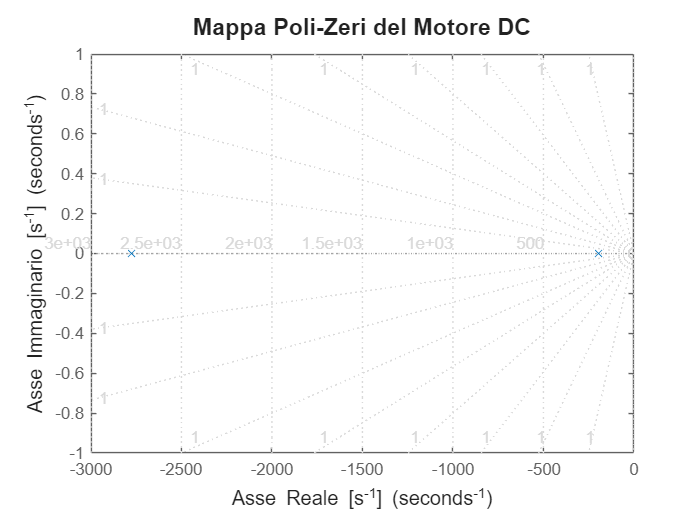

s = tf('s');
G_motore_elettr = 1/(La*s+Ra);
G_motore_mecc = 1/(J*s+b);
G_motore= (Kt/(J*La))/(s^2 + (Ra/La)*s + (Kt*Ke)/(J*La));
figure; 
pzmap(G_motore)
grid on
title('Mappa Poli-Zeri del Motore DC', 'FontSize', 14)
xlabel('Asse Reale [s^{-1}]', 'FontSize', 12)
ylabel('Asse Immaginario [s^{-1}]', 'FontSize', 12)

Il sistema è **stabile** con poli reali negativi. In particolare risulta **sovrasmorzato** in quanto i poli hanno parte immaginaria nulla nel piano.

damp(G_motore)

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
 -1.97e+02     1.00e+00       1.97e+02         5.07e-03    
 -2.78e+03     1.00e+00       2.78e+03         3.60e-04    


Si analizza la risposta al gradino unitario per studiare le prestazioni dinamiche del sistema.

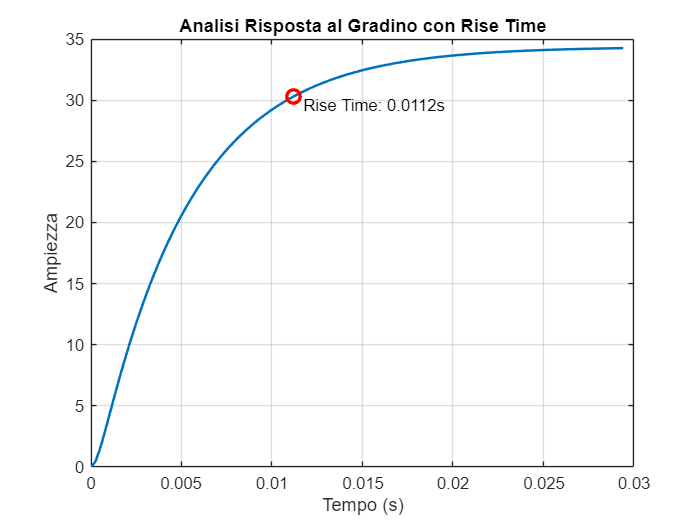

[y, t] = step(G_motore);
info = stepinfo(G_motore);
plot(t, y, 'LineWidth', 1.5);
grid on; hold on
[~, idxTR] = min(abs(t - info.RiseTime)); 
plot(t(idxTR), y(idxTR), 'ro', 'MarkerSize', 8, 'LineWidth', 2);
text(t(idxTR), y(idxTR), ['  Rise Time: ', num2str(info.RiseTime, 3), 's'], 'VerticalAlignment', 'top')
title('Analisi Risposta al Gradino con Rise Time');
xlabel('Tempo (s)');
ylabel('Ampiezza');
hold off

Sebbene il motore DC sia intrinsecamente stabile in anello aperto e abbia anche buone caratteristiche dinamiche (overshoot nullo e rising time piccolo), la progettazione di un un sistema di controllo in cascata consente di garantire un'elevata reiezione ai disturbi di carico o ai rumori esterni monitorando, al tempo stesso, l'andamento delle grandezze elttriche e soddisfando specifici requisiti prestazionali: tempo di salita (rising time) ridotto, sovraelongazione (overshoot) contenuta ed errore a regime nullo.

#### Caratteristiche del  convertitore H bridge**:**

Il chip del convertitore H bridge scelto per alimentare il motore è il [STMicroelectronics VNH7070AS](https://www.st.com/en/automotive-analog-and-power/vnh7070as.html) Il convertitore risulta avere una tensione nominale sufficiente per alimentare il motore a 24V e il chip lavorerà a temperature non elevate considerando che la corrente nominale (15A) è nettamente superiore della corrente nominale del motore (3.81A). Inoltre risulta essere dotato di pin *MultiSense* utile per implementare una retroazione di corrente. Allo spunto o durante un blocco meccanico (stallo), la corrente del  motore subisce variazioni brusche che possono danneggiare i MOSFET dell' H bridge, pertanto si deve implementare un controllo in retroazione sulla corrente del motore. Il controllore PID di velocità avrà una saturazione sulla corrente impostata a Imax +/- 10A valore accettabile dal motore dato che lo spunto è un fenomeno transitorio del sistema. Per evitare l’accumulo dell’azione integrativa durante le fasi di saturazione e ridurre il rischio di sovraelongazioni eccessive e tempi di assestamento elevati, occorre implementare un meccanismo di **anti-windup *****clamping*** nel controllore. 

La regolazione della tensione avviene tramite **tecnica PWM**. Il controllore PI di corrente genera un segnale modulante che, confrontato con una portante a dente di sega, definisce il **Duty Cycle** necessario a mantenere il set-point desiderato.


$$\frac{V_{\textrm{in}} }{V_{\textrm{out}} }=\textrm{duty}\;\textrm{cycle}=$$

$$\frac{V_c }{V_p }$$


In ottica di ottimizzazione dei pesi, dei costi e degli ingombri del sistema di azionamento (*packaging*), non è stato introdotto alcun filtro analogico LC ausiliario all'uscita del ponte H. L'induttanza di armatura del motore DC funge già da filtro passa-basso naturale rispetto alla frequenza di portante del PWM, garantendo un corretto livellamento della corrente senza componenti aggiuntivi. Difatti la frequenza di commutazione del PWM è 20KHz e risulta sufficientemente più alta della frequenza di taglio del filtro costituito da $L_a$ e $R_a$.

fpwm > Ra/2*pi*La*1000

ans = logical
   1


L’H-bridge PWM è stato modellato mediante un modello medio continuo equivalente, rappresentato da un guadagno statico pari alla tensione di alimentazione e da una dinamica del primo ordine che considera il ritardo introdotto dalla modulazione PWM e dall’elettronica di potenza $\tau_s$ .


$$G_{\textrm{conv}} =\frac{V_a }{\textrm{duty}\;\textrm{cycle}}=\frac{24}{\tau_s \cdot s+1}$$


G_conv = 24/((4.5e-5*s)+1);

Il duty cycle del convertitore è limitato tra +1 e -1 e introduce saturazione nel segnale di comando. Per evitare l’accumulo dell’azione integrativa durante le fasi di saturazione e ridurre il rischio di sovraelongazioni eccessive e tempi di assestamento elevati, occorre implementare un meccanismo di anti-windup *clamping* nel controllore PI di corrente.

#### Dinamica del sensore di velocità

Per la catena di feedback si è ipotizzato l'utilizzo del sensore di velocità  integrato al motore. Trattandosi di un encoder ottico con frequenza di campionamento di 1000 Hz il suo modello dinamico può essere approssimato ad un guadagno unitario. Tale semplificazione è giustificata dal fatto che la larghezza di banda del trasduttore è significativamente superiore alla frequenza di crossover del loop di controllo, rendendo i ritardi di misura trascurabili per la stabilità del sistema. Tuttavia per prevenire il fenomeno dell'**aliasing** dovuto al rumore di commutazione del convertitore, è stato introdotto un **filtro passa-basso analogico** nel blocco sensore. La frequenza di taglio è stata calibrata per essere inferiore alla frequenza di Nyquist (500Hz) del sistema di acquisizione digitale, garantendo un'accurata ricostruzione del feedback di velocità. la funzione di trasferimento sarà pertanto:


$$H_s \left(s\right)=\frac{1}{1+\tau_{\textrm{sens}} \cdot s}$$
                 
$$\tau_{\textrm{sens}} =\frac{1}{2\cdot 3,14\cdot f_c }=\frac{1}{2\cdot 3,14\cdot 100}=0,0016\;s$$


fc = 100;                        % frequenza di taglio del filtro
tau_s = 1 / (2 * pi * fc);       % costnate di tempo
Ks = 1;                          % guadagno unitario sensore
num_sens = Ks;
den_sens = [tau_s 1];
H_s = tf(num_sens,den_sens);     %funzione di trasferimento del sensore

## Analisi del Sistema :

E' utile anche osservare la risposta in frequenza del sistema in *open loop *attraverso i diagrammi di ampiezza e di fase di bode per studiarne i margini di stabilità:

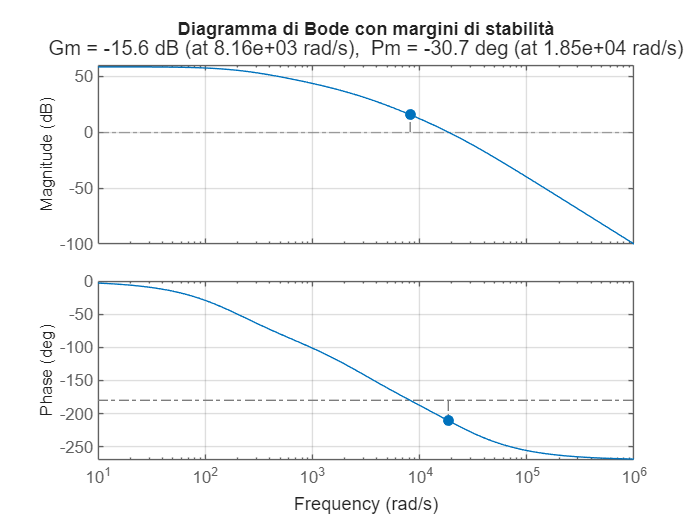

figure
margin(G_motore*G_conv)   
grid on
title('Diagramma di Bode con margini di stabilità')

Dall’analisi dei diagrammi di Bode del sistema in anello aperto il comportamento in frequenza evidenzia caratteristiche di tipo passa-basso, con una significativa attenuazione delle componenti ad alta frequenza, che si traduce in una limitata banda passante. L’azione del controllore PID consente di incrementare la banda passante del sistema, rendendolo più reattivo alle variazioni della velocità di riferimento e del carico. La funzione di trasferimento in anello aperto del sistema convertitore-motore presenta un** margine di fase negativo**, evidenziando un'intrinseca **instabilità in caso di chiusura dell'anello** **senza l'utilizzo del PID**.

## Limiti termici e meccanici del sistema :

Per la simulazione è stata scelta una **velocità target di 250 rad/s** corrispondenti circa a 2388 rpm ben al di sotto della velocità nominale del motore. Il **carico è una coppia costante di 0.08 Nm** ben al di sotto dei 0.108 Nm di coppia nominale del motore ed è stato modellato come un disturbo esterno per verificare quantitativamente la robustezza e la stabilità dei controllori implementati. Dal punto di vista termico occorre monitorare la temperatura degli avvolgimenti del motore nel caso in cui si abbiano tempi lunghi di saturazione (con corrente di 10A o maggiore della corrente nominale del motore) che possono portare sovratemperature eccessive. 

Sebbene i transitori dinamici impulsivi (nell'ordine dei millisecondi) presentino un impatto termico trascurabile per gli avvolgimenti, è stata implementata una logica di monitoraggio temporale sulla corrente e sul duty cycle attraverso gli **scope** di Simulink. Tale strategia funge da diagnostica predittiva per il rilevamento tempestivo dello stallo meccanico del rotore, prevenendo il danneggiamento termico del componente.

## Progettazione del Controllore:

La regolazione del servomotore è stata sviluppata mediante un’architettura di controllo in cascata, costituita da un anello interno dedicato al controllo della corrente (e quindi della coppia) e da un anello esterno per il controllo della velocità.

In una prima fase, il tuning dei regolatori di corrente e velocità è stato effettuato trascurando gli effetti di non linearità introdotti dalle saturazioni del duty cycle e della corrente, al fine di semplificare l’analisi e la progettazione del sistema di controllo.

Successivamente, è stata verificata la robustezza del sistema anche in presenza delle saturazioni, analizzando l’andamento della velocità e della corrente tramite gli scope di Simulink. I risultati delle simulazioni hanno permesso di valutare il comportamento dinamico del sistema e di confermare la validità della strategia di controllo adottata

#### 1. Tuning dell'Anello Interno di Corrente

Il controllo sull'anello di corrente è affidato a un regolatore di tipo **PI Proporzionale-Integrale**, con $\(K_d = 0\)$.  I parametri$\(K_{p}\) e \(K_{i}\) $sono stati dimensionati applicando il metodo analitico della cancellazione polo-zero, finalizzato a compensare esattamente il polo elettrico del motore $\tau_e = L_a/R_a\))$. Questa calibrazione è stata impostata per rendere la dinamica dell'anello interno estremamente più rapida rispetto a quella dell'anello esterno di velocità. Sotto tali condizioni di separazione in frequenza, l'intero anello di corrente si comporta, dal punto di vista del controllore esterno, come un sistema istantaneo. 

#### 2. Tuning dell'Anello Esterno di Velocità

Sebbene l'ambiente Simulink consenta l'utilizzo di strumenti di ottimizzazione automatica (*PID Tuner*) per l'anello esterno, la taratura dei parametri relativi al PID è stata eseguita manualmente tramite una procedura di *trial and error.*

La calibrazione ha seguito i seguenti passi:

- **Azione Proporzionale **$K_{p}\))$: Si è incrementato gradualmente il guadagno proporzionale al fine di aumentare la prontezza del sistema e minimizzare il tempo di salita (*rise time*).

- **Azione Integrale **$\(K_{i}\)$: Successivamente, si è aumentato il guadagno integrale per garantire l'annullamento completo dell'errore a regime permanente rispetto al riferimento di velocità.

- **Azione Derivativa **$\(K_{d}\)$: Per evitare l'amplificazione del rumore ad alta frequenza sulla misura del sensore di velocità (legato alla frequenza di campionamento e ai filtri di aliasing), si è scelto di escludere l'azione derivativa $\(K_d = 0\)$, preservando la stabilità del segnale di controllo.

La coesistenza di azioni integrali saturazioni ha richiesto particolare attenzione per evitare il fenomeno dell'**integrator windup**. Quando il sistema lavora in saturazione (ad esempio durante il forte transitorio iniziale o a seguito del gradino di carico), l'errore non si azzera immediatamente e l'azione integrale continua ad accumulare energia a vuoto. Questo comportamento genera enormi sovraelongazioni (*overshoot*) e instabilità nel ritorno alla zona lineare. Per ovviare a questo problema, in entrambi i regolatori (corrente e velocità) è stata implementata una tecnica di Anti-Windup di tipo **Clamping**. Tale algoritmo congela l'azione integrale non appena l'uscita del controllore tocca i limiti fisici imposti, garantendo un rientro rapido e privo di oscillazioni distruttive nella zona di funzionamento lineare.

Per valutare il sistema in termini di prestazioni dinamiche è stata datta un'analisi dei principali parametri dello *step e impulse response *e dei diagrammi di Bode per verificare la robustezza e il margine di fase e di stabilità. Di seguito se ne riportano i grafici :

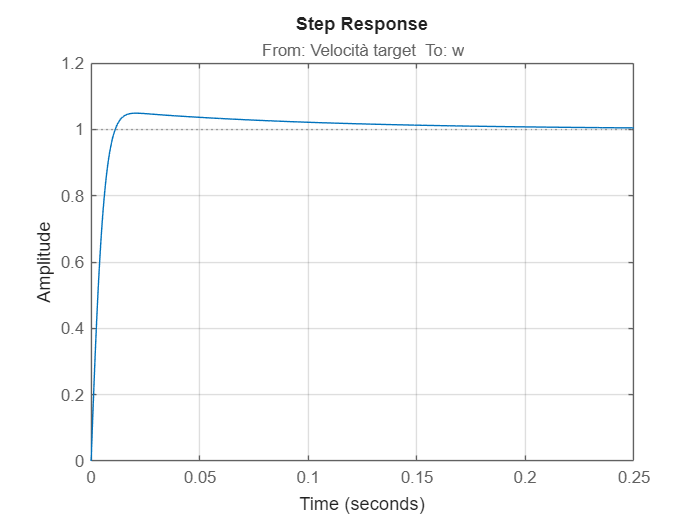

open_system("simulink_tuning.slx");
out=sim("simulink_tuning.slx");
io = getlinio('simulink_tuning');
sys = linearize('simulink_tuning', io);
stepplot(sys);
grid on

info = stepinfo(sys);
struct2table(info)

ans = 1×9 table
    RiseTime     TransientTime    SettlingTime    SettlingMin    SettlingMax    Overshoot    Undershoot     Peak     PeakTime
    _________    _____________    ____________    ___________    ___________    _________    __________    ______    ________

    0.0072464       0.10598         0.10598         0.90505        1.0487        4.8667          0         1.0487    0.020775


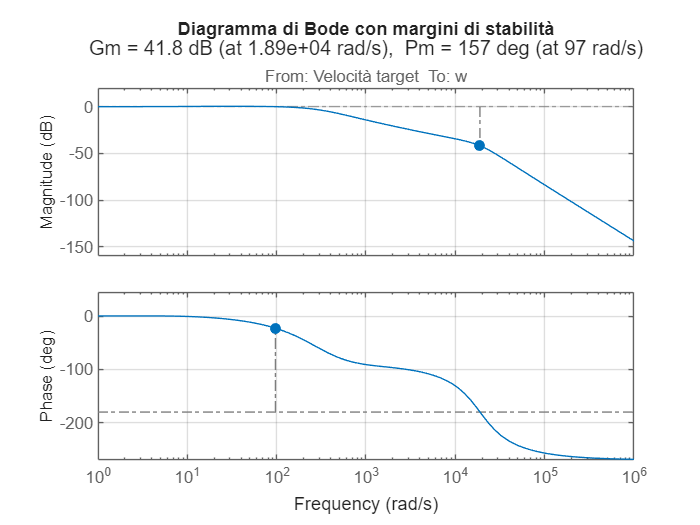

figure
margin(sys)   
grid on
title('Diagramma di Bode con margini di stabilità')

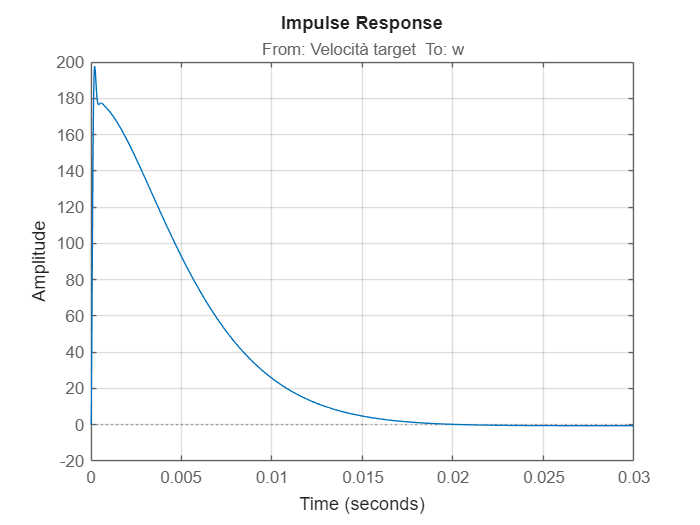

impulseplot(sys)
grid on

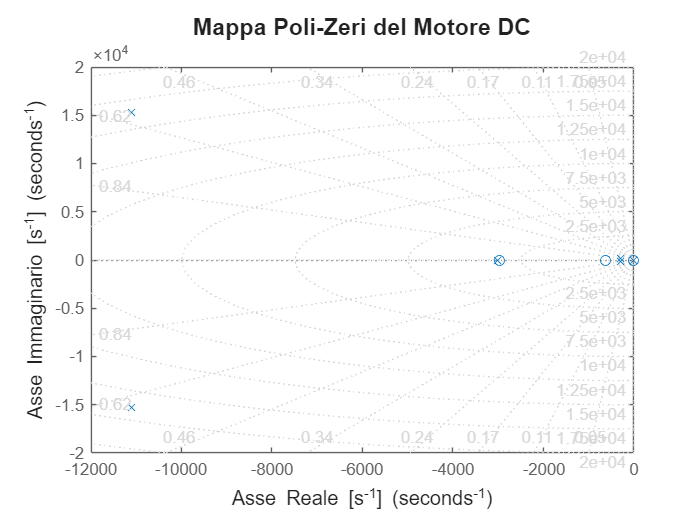

figure; 
pzmap(sys)
grid on
title('Mappa Poli-Zeri del Motore DC', 'FontSize', 14)
xlabel('Asse Reale [s^{-1}]', 'FontSize', 12)
ylabel('Asse Immaginario [s^{-1}]', 'FontSize', 12)

Il sistema risulta stabile, con buone prestazioni dinamiche ; **overshoot < 5%** , **errore a regime nullo**, **rising time** molto veloce di circa **7ms, settling time 0.106ms **e **margine di fase di 157°. **Occorre pertanto passare alla simulazione reale del sistema in presenza di saturazioni e disturbi esterni (coppia di carico) per verificarne la reiezione.

#### 4. Simulazione

Per validare la robustezza e la stabilità del controllo in cascata così progettato, al secondo $\(t = 0.5\text{ s}\)$ è stata applicata una **coppia di carico** pari a $\(0.08\text{ Nm}\)$ sotto forma di disturbo a gradino. Inoltre sono state aggiunte le **saturazioni di corrente e duty cycle**. Lo schema a blocchi finale risulta essere rappresentato di seguito.

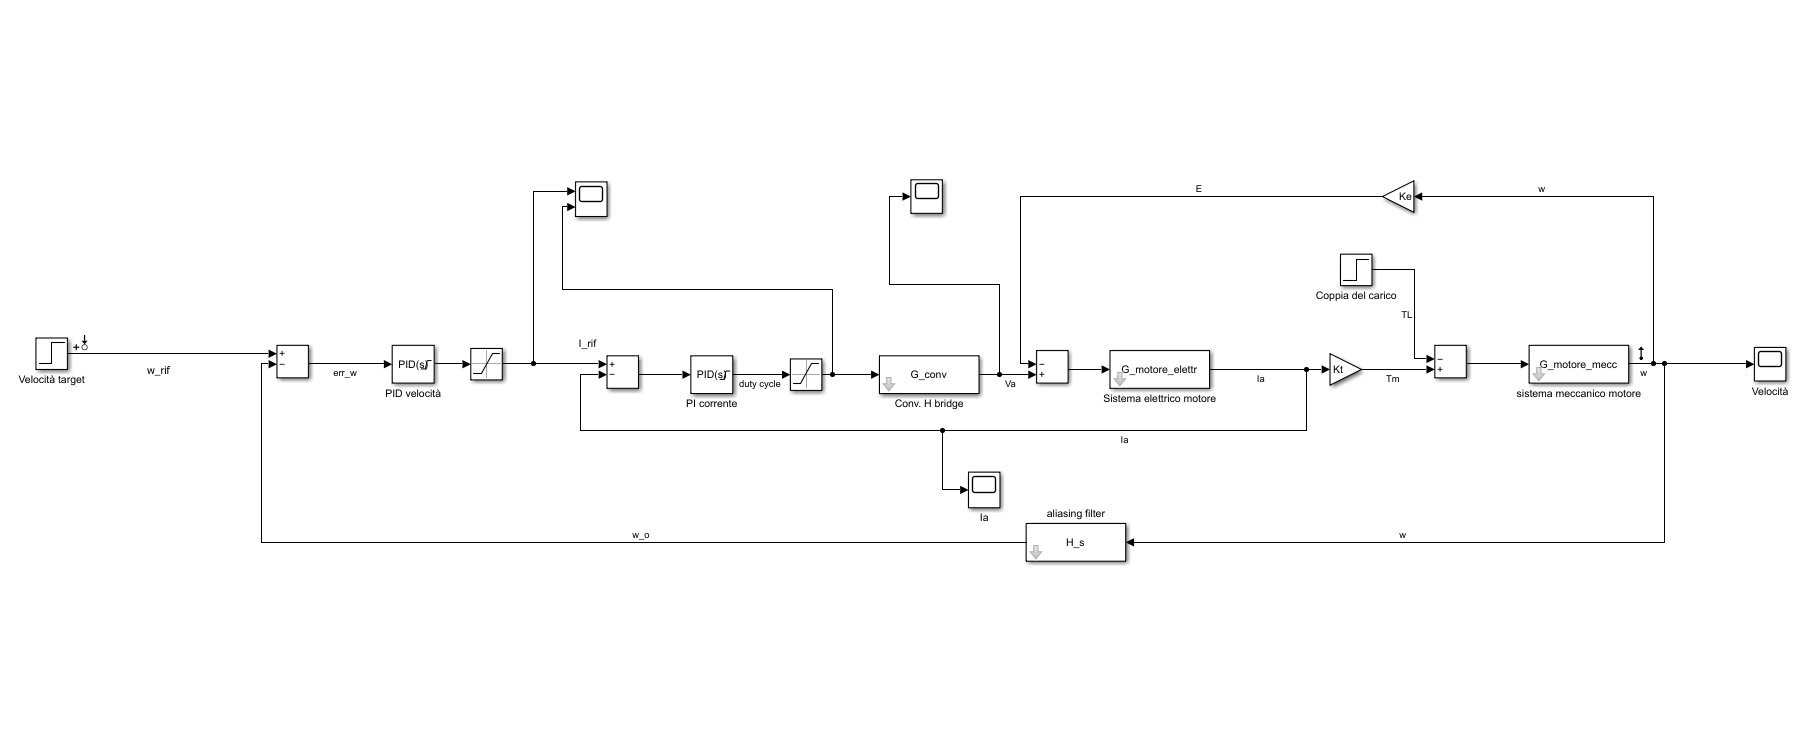

Si analizza l'andamento della velocità *w *nel tempo attraverso lo scope di Simulink.

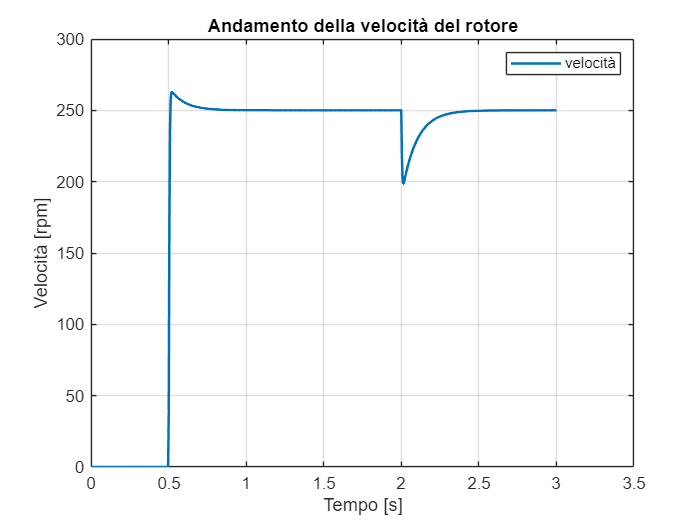

figure;
plot(out.output_velocita.time, out.output_velocita.signals.values, 'LineWidth', 1.5);
hold on;
grid on;
title('Andamento della velocità del rotore');
xlabel('Tempo [s]');
ylabel('Velocità [rpm]');
legend('velocità');

La simulazione ha confermato l'ottima capacità di reiezione ai disturbi del sistema: grazie all'azione combinata del controllo in cascata e dell'anti-windup, l'anello ha compensato rapidamente la caduta di velocità transitoria dovuta all'innesto di una coppia di carico all'istante *t=2s *, riportando l'uscita al valore di riferimento nominale di $\(250\text{ rad/s}\)$ in pochi millisecondi e con un overshoot contenuto ampiamente sotto il limite del $\(5\%\)$.

Per valutare l'impatto del sistema di controllo e del carico applicato, si può osservare l'andamento della corrente di armatura del motore.

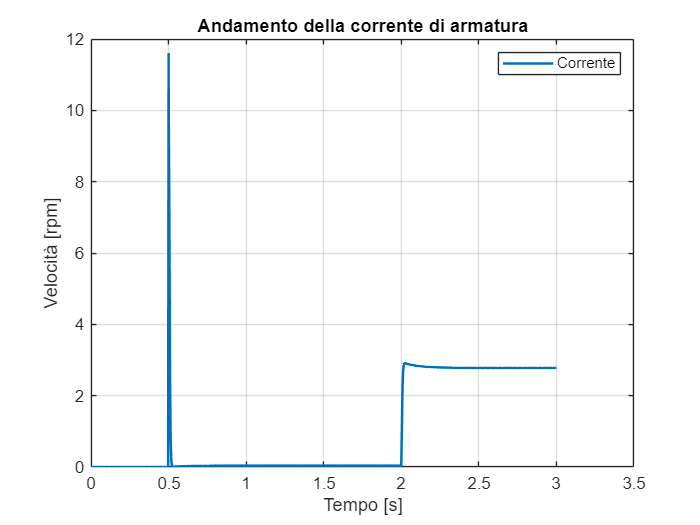

figure;
plot(out.corrente.time,out.corrente.signals.values, 'LineWidth', 1.5);
hold on;
grid on;
title('Andamento della corrente di armatura');
xlabel('Tempo [s]');
ylabel('Velocità [rpm]');
legend('Corrente')

Il grafico della corrente rispecchia perfettamente il principio di funzionamento di un motore DC. Allo spunto (quando viene applicato il gradino di riferimento a 250 rad/s), la corrente raggiunge un valore di picco elevato. Il sistema reagisce velocemente e la corrente diminuisce fino ad arrivare quasi a 0. Difatti anche in assenza di coppia di carico la corrente non è esattamente 0 perchè deve produrre una coppia per vincere gli attriti, l'inerzia del motore e le perdite nel ferro per isteresi e correnti parassite. Quando viene applicata il carico all'istante *t=2s , *il sistema è costretto a vincere tale coppia per riportare la velocità al valore di riferimento nel minor tempo possibile e quindi il motore assorbe una corrente maggiore. A regime per mantenere il riferimento di velocità la corrente si stabilizza intorno a 2.7 A che è inferiore rispetto al valore nominale del motore.